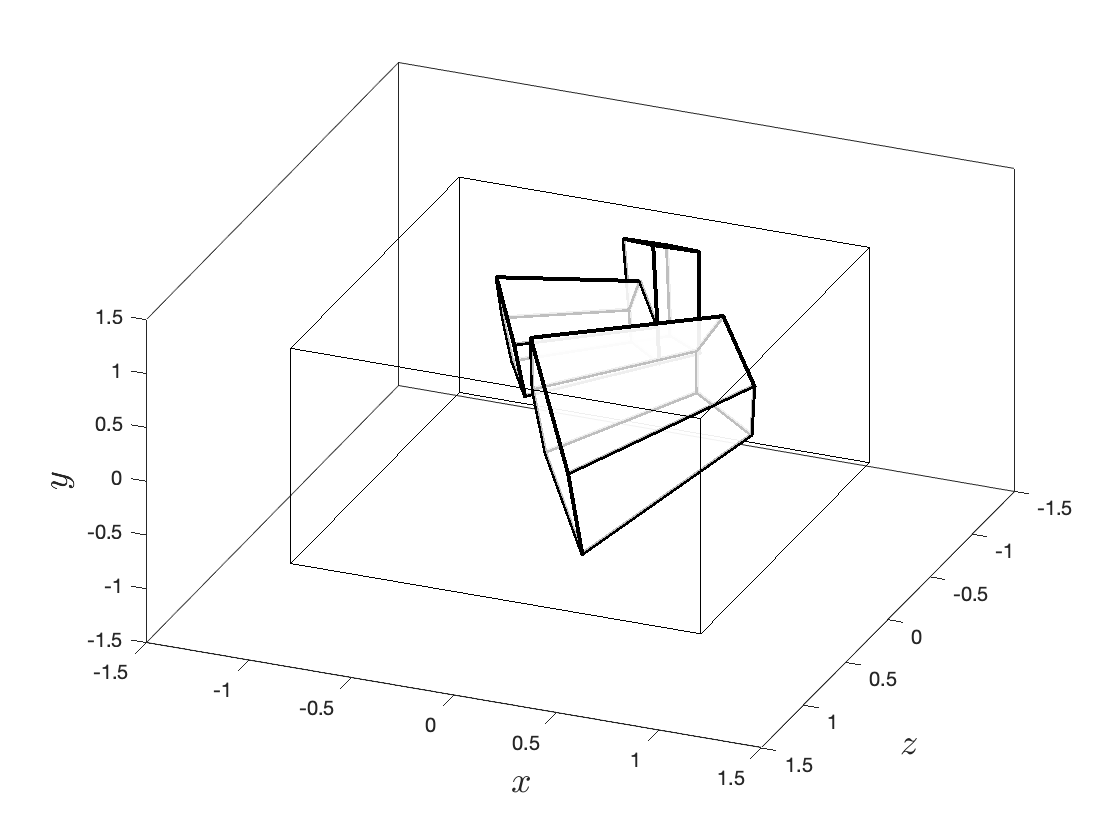

clear

% Load world space coordinates
load('camera_space_coords.mat')

% Define projection parameters
near = 1;
far = 5;
fov = pi/4;
aspect = 4/3;

% Unit cube
Vcube = [-1, 1, 1, -1, -1, 1, 1, -1 ; -1, -1, 1, 1, -1, -1, 1, 1 ; -1, -1, -1, -1, 1, 1, 1, 1 ; 1, 1, 1, 1, 1, 1, 1, 1];
Fcube = [4, 3, 2, 1 ; 1, 2, 6, 5 ; 2, 3, 7, 6, ; 3, 4, 8, 7 ; 1, 5, 8, 4 ; 5, 6, 7, 8];

% Calculate projection matrix
r = 2 * tan(fov / 2);
t = r / aspect;
P = [-near / r, 0, 0, 0 ;
     0, -near / t, 0, 0 ;
     0, 0, (near + far) / (near - far), 2 * near * far / (near - far) ;
     0, 0, 1, 0 ];

% Calculate screen space co-ordinates
Vscreen = P * Vcamera;
Vscreen = Vscreen ./ Vscreen(4,:);

% Plot camera space (from viewing position)
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', F, FaceColor='w', FaceAlpha=0.75, LineWidth=2)
patch('Vertices', Vcube(1:3,:)', 'Faces', Fcube, FaceAlpha=0)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 18)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 18)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 18)
set(h1, 'Ydir', 'reverse')
view(0,0)
axis([-1.5, 1.5, -1.5, 1.5, -1.5, 1.5])
box on


exportgraphics(gcf,'../images/clipping.png','Resolution',300) 


[Vclipped, Fclipped] = sutherland_hodgman(Vscreen, F)

P =     -1    -1    -1     1     1     1
    -1    -1    -1     1     1     1
     1     1     1    -1    -1    -1


n =      0     0    -1     0     1     0
     1     0     0     0     0    -1
     0    -1     0     1     0     0


inputlist =      4     3     2     1     1


inputlist =     29    30     3     2     1     1


inputlist =     29    30     3     2     1     1



inputlist =

     []


inputlist =

     []


inputlist =

     []



Vclipped =     0.5525    0.2254   -0.3566         0    0.5855    0.2363   -0.3846         0    0.4144   -0.2515         0   -0.1648   -0.6763   -0.5525         0   -0.1705   -0.7089   -0.5855   -0.0952   -0.6906         0   -0.1648         0    0.1648         0   -0.1833         0    0.1833    0.2915   -0.2915
   -0.6412   -0.4709   -0.9105   -1.4007   -0.1359   -0.0548   -0.2678   -0.5203    0.4168    0.5253   -0.3536   -0.2678   -0.4709   -0.6412    0.0000    0.0396   -0.0548   -0.1359    0.3757    0.4168   -0.2023   -0.2678   -0.3536   -0.2678    0.6662    0.7233    0.8004    0.7233   -1.0000   -1.0000
   -0.6909   -0.8397   -0.4555   -0.0270   -0.6426   -0.8079   -0.3736    0.1413   -0.6909   -0.0270   -0.9423   -1.0173   -0.8397   -0.6909   -0.9197   -1.0005   -0.8079   -0.6426   -0.9423   -0.6909   -1.0745   -1.0173   -0.9423   -1.0173   -1.0330   -0.9631   -0.8687   -0.9631   -0.3773   -0.3773
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.


Fclipped =

     []



function [Vclipped, Fclipped] = sutherland_hodgman(V, F)

% Define clipping cube
P = [ -1, -1, -1, 1, 1, 1 ; 
      -1, -1, -1, 1, 1, 1 ; 
       1, 1, 1, -1, -1, -1];
n = [ 0, 0, -1, 0, 1, 0 ;  
      1, 0, 0, 0, 0, -1 ; 
      0, -1, 0, 1, 0, 0];

% Loop through the polygons in F
[npoly, maxverts] = size(F);
Vclipped = V;
Fclipped = [];

for poly = 1 : 1

    % Loop through the edges of the clipping cube
    outputlist = F(poly, :);
    for edge = 1 : 6
        inputlist = outputlist
        outputlist = [];

        for i = 1 : length(inputlist)
            current = inputlist(i);
            previous = inputlist(mod(i - 2,4) + 1);

            % Calculate intersection point

            dcurrent = dot(Vclipped(1:3,current) - P(:,edge), n(:,edge));
            dprevious = dot(Vclipped(1:3,previous) - P(:,edge), n(:,edge));
%             [P(:,edge), n(:,edge)]
%             [dcurrent, dprevious]
            if dcurrent - dprevious ~= 0
                t = dprevious / (dprevious - dcurrent);
                intersection = [Vclipped(1:3,previous) + t * (Vclipped(1:3,current) - Vclipped(1:3,previous)) ; 1];
            end

            % Check if polygon edge crosses clipping cube edge
            if dcurrent > 0 
                % if previous point is outside add intersection to output list
                if dprevious < 0 
                    Vclipped = [Vclipped, intersection];
                    outputlist = [outputlist, size(Vclipped, 2)];
                end
                outputlist = [outputlist, current];

            elseif dprevious > 0
                % current point is outside and previous point is inside so add
                % intersection to output list
                Vclipped = [Vclipped, intersection];
                outputlist = [outputlist, size(Vclipped, 2)];
            end
        end
    end

    % If outputlist is non-empty add to Fclipped
    if isempty(outputlist) == 0
        nclippedverts = length(outputlist);

        if maxverts < nclippedverts
            % Pad out Fclipped if number of clipped vertices is greater
            % than current maxverts
            Fclipped = [Fclipped, zeros(size(Fclipped, 1), nclippedverts - maxverts)];
            Fclipped(:,maxverts + 1 : end) = Fclipped(:, maxverts);
            maxverts = nclippedverts;

        elseif maxverts > length(outputlist)
            % Pad out outputlist if number of clipped vertices is less than
            % current maxverts
            outputlist = [outputlist, ones(1,maxverts - nclippedverts) * outputlist(end)];
        end

        % Add outputlist to Fclipped
        Fclipped = [Fclipped ; outputlist];
    end

end


end